# Lab 7: Splines - Submission

Name: Lilith Janevska

## Problem 1 Answer

#### Part a

% nodes_x = -1.5:3/(10-1):1.5; 
% nodes_x = transpose(nodes_x);
% nodes_fx = (cos(2.5.*pi.*nodes_x)).*exp(-1.*(nodes_x.^2));
% Poly = MyLagrangeInterpolator(nodes_x,nodes_fx);
% 
% nodes_x = -1.5:3/(20-1):1.5;  
% nodes_x = transpose(nodes_x);
% nodes_fx = (cos(2.5.*pi.*nodes_x)).*exp(-1.*(nodes_x.^2));
% Poly2 = MyLagrangeInterpolator(nodes_x,nodes_fx);
% 
% x = -1.5:0.003:1.5;
% y = (cos(2.5.*pi.*x)).*exp(-1.*(x.^2));
% y1 = Poly(x);
% y2 = Poly2(x);
% 
% hold on
% plot(x,y,Color='RED',LineWidth=1.5)
% plot(x,y1,Color='Blue',LineWidth=1.5)
% plot(x,y2,Color='Green',LineWidth=1.5)
% hold off
% 
% 
% E = max(max(abs(((cos(2.5.*pi.*x)).*exp(-1.*(x.^2)))-Poly(x))))
% E = max(max(abs(((cos(2.5.*pi.*x)).*exp(-1.*(x.^2)))-Poly2(x))))

function [result] = MyLagrangeInterpolator(nodes_x,nodes_fx)
    Poly = @(x) 0;
    
    i = 0;
    while i < length(nodes_x)
        p = @(x) 1;
        
        i2 = 0;
            while i2 < length(nodes_x)
                if i2 == i
                    i2 = i2 + 1;
                    continue
                else
                    p = @(x) (p(x)).*((x-nodes_x(i2+1,1))/(nodes_x(i+1,1)-nodes_x(i2+1,1)));
                    i2 = i2 + 1;
                end
            end
        p = @(x) (nodes_fx(i+1,1)).*(p(x));
        Poly = @(x) Poly(x)+p(x);
        i = i + 1;
    end

    result = Poly;
end

Results:

E10 =

    2.5222


E20 =

    1.2668

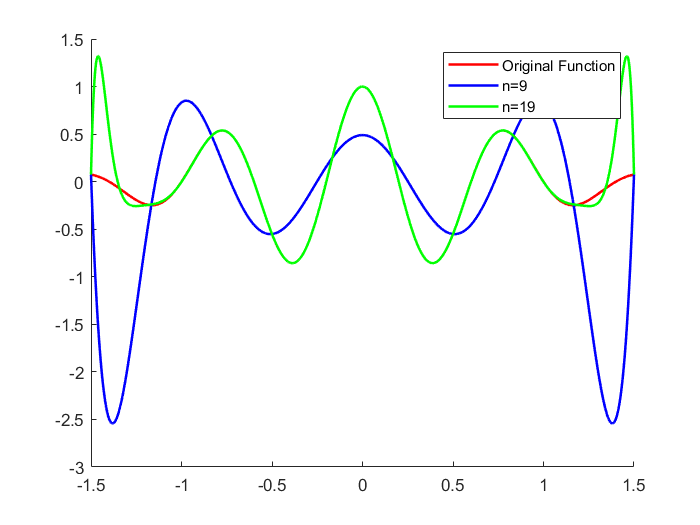

#### Part b

nodes_x = -1.5:3/(10-1):1.5; 
nodes_fx = (cos(2.5.*pi.*nodes_x)).*exp(-1.*(nodes_x.^2));
v_l = -0.36176;
v_r = 0.36176;
CS1 = csape(nodes_x,[v_l nodes_fx v_r]);

nodes_x = -1.5:3/(20-1):1.5;  
nodes_fx = (cos(2.5.*pi.*nodes_x)).*exp(-1.*(nodes_x.^2));
CS2 = csape(nodes_x,[v_l nodes_fx v_r]);

x = -1.5:0.003:1.5;
y = (cos(2.5.*pi.*x)).*exp(-1.*(x.^2));
y1 = ppval(CS1,x);
y2 = ppval(CS2,x);

hold on
plot(x,y,Color='RED',LineWidth=1.5)
plot(x,y1,Color='Blue',LineWidth=1.5)
plot(x,y2,Color='Green',LineWidth=1.5)
legend("Original Function","n=9","n=19");
hold off


E = max(max(abs(((cos(2.5.*pi.*x)).*exp(-1.*(x.^2)))-ppval(CS1,x))))
E = max(max(abs(((cos(2.5.*pi.*x)).*exp(-1.*(x.^2)))-ppval(CS2,x))))

Results:

E10 =

    0.5192


E2 =

    0.0117

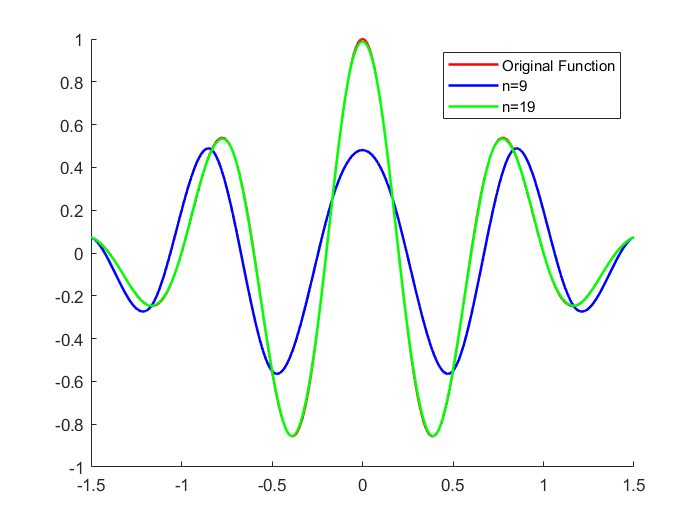

## Problem 2 Answer

nodes_x = 0:1/(12-1):1; 
nodes_fx = (cos(sin(4.*pi.*nodes_x))).*exp(-1.*(nodes_x.^3));
v_l = 0;
v_r = -3/exp(1);
CS1 = csape(nodes_x,[v_l nodes_fx v_r]);

nodes_x = 0:1/(12-1):1;  
nodes_fx = (cos(sin(4.*pi.*nodes_x))).*exp(-1.*(nodes_x.^3));
CS2 = csape(nodes_x,nodes_fx,"variational");

x = 0:0.001:1;
y = (cos(sin(4.*pi.*x))).*exp(-1.*(x.^3));
y1 = ppval(CS1,x);
y2 = ppval(CS2,x);

hold on
plot(x,y,Color='RED',LineWidth=1.5)
plot(x,y1,Color='Blue',LineWidth=1.5)
plot(x,y2,Color='Green',LineWidth=1.5)
legend("Original Function","Clamped","Normal");
hold off


E = max(max(abs((cos(sin(4.*pi.*x))).*exp(-1.*(x.^3))-ppval(CS1,x))))
E = max(max(abs((cos(sin(4.*pi.*x))).*exp(-1.*(x.^3))-ppval(CS1,x))))

Results:

E1 =

    0.0514


E2 =

    0.0514

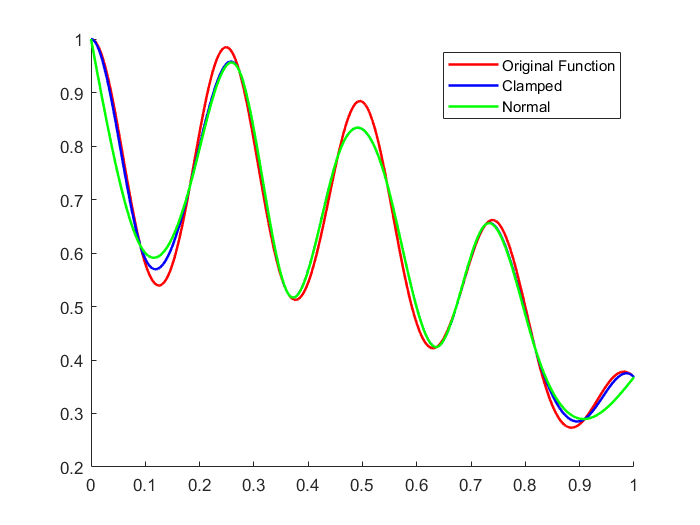

As can be seen, both methods preform the same in the middle, but near the ends the clamped spline matches the true function much better than the normal spline.

## Problem 3 Answer

#### Part a

load("new jersey home prices.mat")

x1 = dates;
y1 = prices;
x2 = incomplete_dates;
y2 = incomplete_prices;

hold on
plot(x1,y1,"Red",LineWidth=1.5)
xlabel("Date")
ylabel("Price")
plot(x2,y2,"Blue",LineWidth=1.5)

Output:

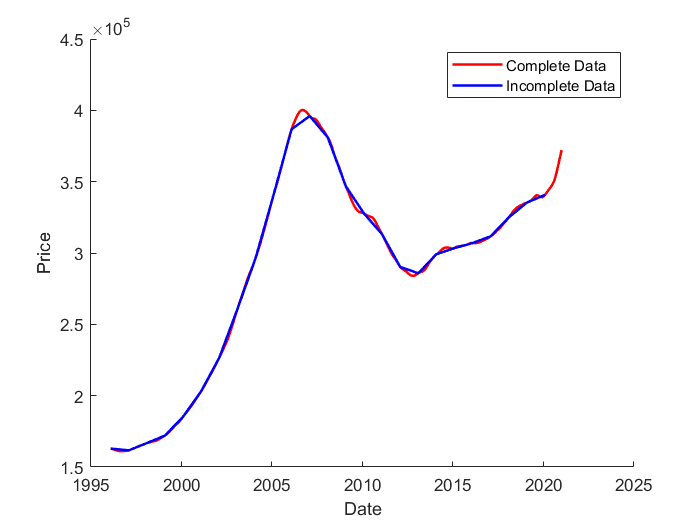

#### Part b

load("new jersey home prices.mat")

x1 = dates;
y1 = prices;

x2 = incomplete_dates;
Spline = csape(x2,incomplete_prices)
x = 1996:1/100:2021
y2 = ppval(Spline,x)

hold on
plot(x1,y1,"Red",LineWidth=1.5)
xlabel("Date")
ylabel("Price")
plot(x,y2,"Blue",LineWidth=1.5)
legend("Complete Data","Incomplete Data");
hold off

Output: